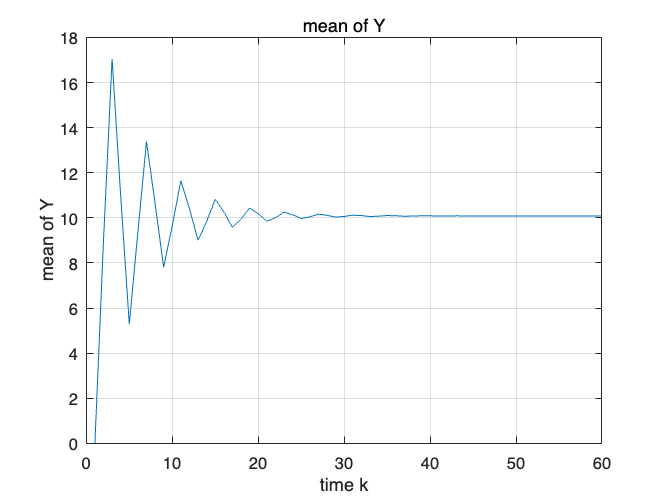

meanw = 10;
N = 60;
meanx = zeros(2,N);
meany = zeros(1,N);

A = [-0.08, -1; 0.7, 0.1];
B = [0.34; 0.3];
C = [0, 3];

Bw = [-0.08, -1; 0.7, 01];

for k = 1:N-1
    meanx(:,k+1) = A*meanx(:,k) + B*meanw; 
    meany(:,k) = C*meanx(:,k);
end
meany(:,N) = C*meanx(:,N);
figure()
plot(meany)
xlabel('time k');
ylabel('mean of Y');
title('mean of Y');
grid on;

% 添加图例说明
%legend('f(l)');

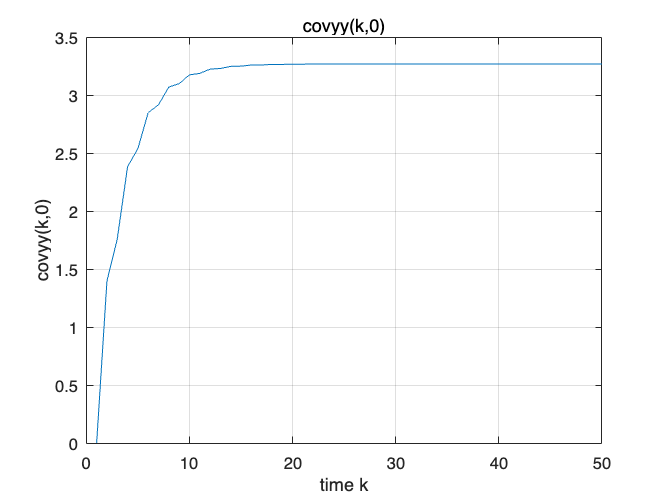


N2=50;

covww=eye(N2);
coxvv=0.5*eye(N2);

covxx = cell(N2,1);
covxx5 = cell(N2,1);
covyy = cell(N2,1);
covyy5 = cell(N2,1);

covxx{1,1} = [0.1,0;0,0.1];

for k = 1:N2
    covxx{k+1,1} = A * covxx{k,1} * (A.') + B * 1 * (B.');
    covyy{k,1} = C*covxx{k,1}*(C.')+ 0.5;

    covxx5{k,1} = A*A*A*A*A* covxx{k,1};
    covyy5{k,1} = C*covxx5{k,1}*(C.');
end

data1(1)=0;
data1(2:N2+1) = cellfun(@double, covyy);
data2(1)=0;
data2(2:N2+1) = cellfun(@double, covyy5);

figure();
plot(data1)
title('covyy(k,0)');
xlabel('time k');
ylabel('covyy(k,0)');
xlim([0 50]);
grid on;

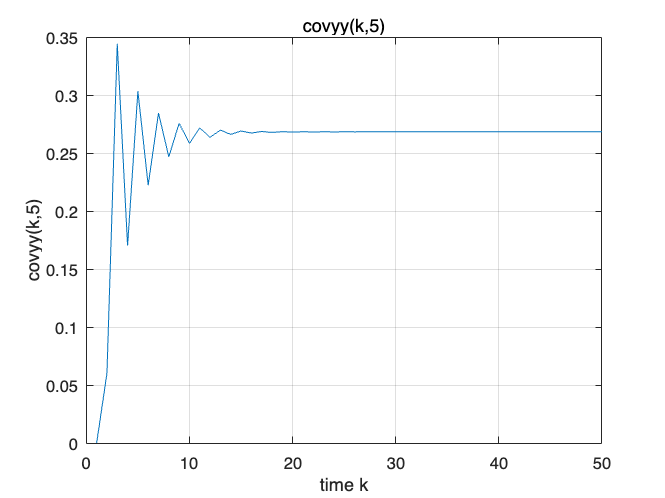


figure();
plot(data2)
title('covyy(k,5)');
xlabel('time k');
ylabel('covyy(k,5)');
xlim([0 50]);
grid on;

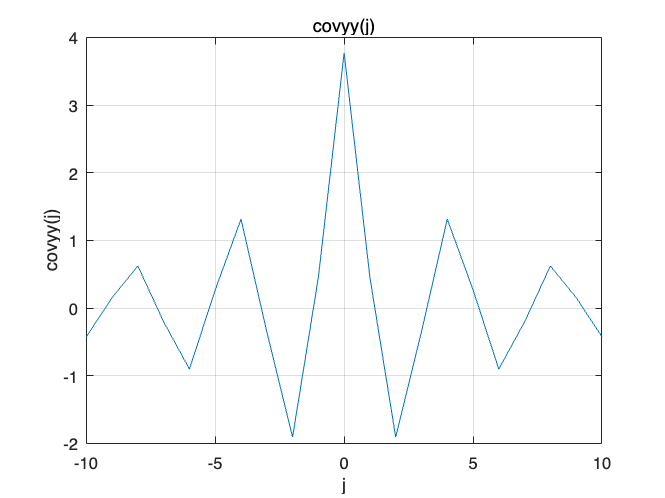

Q = B * 1 * (B.'); 
X = dlyap(A, Q);

Xt = X;
Y(11) = C*Xt*(C.')+ 0.5;
for k = 1:1:10
    Xt = A*Xt;
    Y(k+11) = C*Xt*(C.');
    Y(11-k) = C*(Xt.')*(C.');
end

Y(11) = Y(11)+0.5;
 
figure();
plot(-10:1:10,Y);
title('covyy(j)');
xlabel('j');
ylabel('covyy(j)');
grid on;

x = Y;
% 假设离散时间序列为x，长度为N
N11=length(x);
% 对x进行Z变换
XX = fft(x);
% 绘制傅里叶变换关于w的图像
% plot(w, abs(X_f));
% xlabel('w');
% ylabel('Magnitude');
% title('Magnitude of Fourier Transform');
% 计算频率轴


% 绘制频谱图
plot(0:2*pi, abs(XX));

错误使用 plot
向量长度必须相同。

xlabel('频率(Hz)');
ylabel('幅值');
title('离散序列的傅里叶变换频谱图');